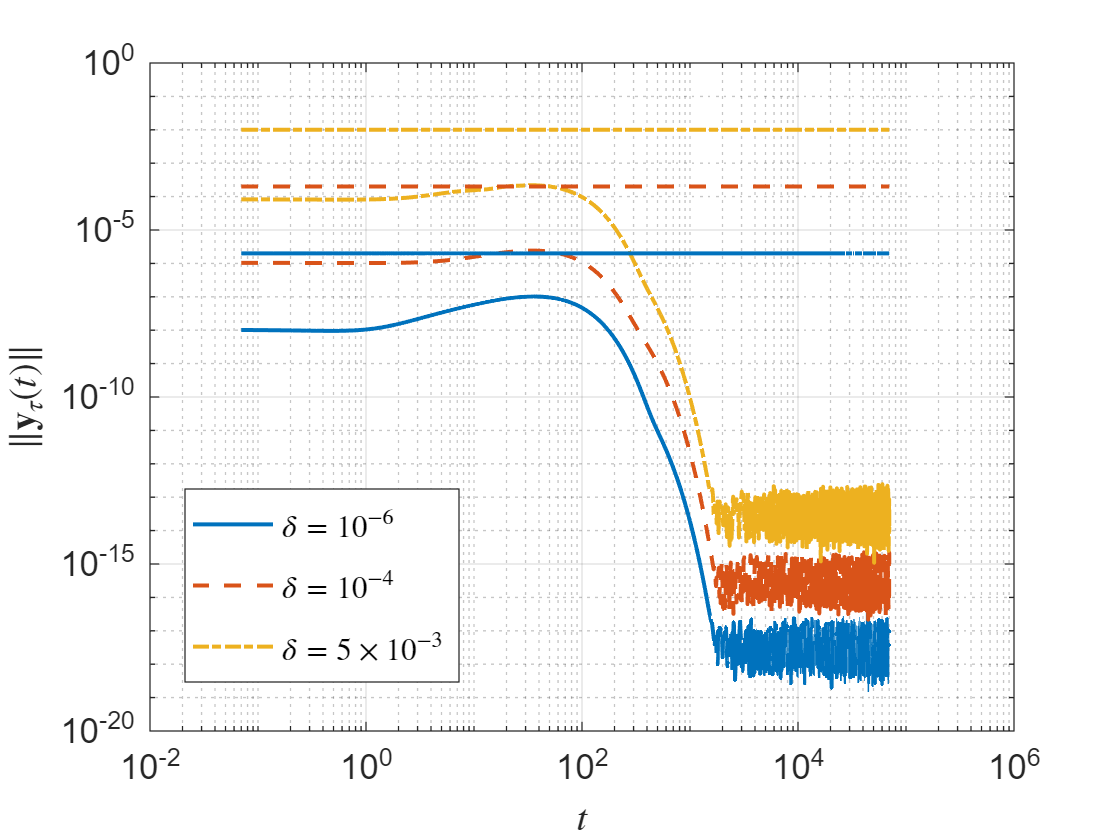

line_styles = {"-","--","-.",":",""};
markers = {'+', 'o', '*', 'x', 's', 'd', '^', 'v', '>', '<', 'p', 'h'};
colors = lines(16);
T = 70000;
t = linspace(0, T, 1000000);
figure;
%             Plot the norm from simulation
%             loglog(t, u_square, 'LineWidth', 1.5, 'DisplayName', 'norm usimulation'); hold on;
            loglog(t, Re_200_1e_6, 'LineWidth', 1.5,'LineStyle', line_styles{1},'Color', colors(1, :)); hold on;
            loglog(t, Re_200_1e_4, 'LineWidth', 1.5,'LineStyle', line_styles{2},'Color', colors(2, :));
            loglog(t,Re_200_5e_3, 'LineWidth', 1.5,'LineStyle', line_styles{3},'Color', colors(3, :));
            % Plot the horizontal line for the upper bound

            loglog(t,Upper_bound_1e_6, 'LineWidth', 1.5,'LineStyle', line_styles{1},'Color', colors(1, :));
            loglog(t,Upper_bound_1e_4, 'LineWidth', 1.5,'LineStyle', line_styles{2},'Color', colors(2, :));
            loglog(t,Upper_bound_5e_3, 'LineWidth', 1.5,'LineStyle', line_styles{3},'Color', colors(3, :));

            %loglog(t, local_u_upper_bound(ind_delta) * ones(size(t)), '--r', 'LineWidth', 1.5, 'DisplayName', 'Upper Bound');
            % Plot Lp norms as horizontal lines
%             loglog(t, u_tau_Lp(ind_p) * ones(size(t)), '--', 'DisplayName', ['Lp Norm (p=', num2str(p_list(ind_p)), ')']); % Lp_norm equal to zero after p=20, may be is numerical problem
%             loglog(t, u_tau_Linf * ones(size(t)), '-.', 'DisplayName', 'L∞ Norm'); % Plot Linf norm
            xlabel('$t$', 'Interpreter', 'latex');
            ylabel('$\|\mathbf{y}_{\tau}(t)\|$', 'Interpreter', 'latex');
            set(gca, 'FontSize', 13);

%             title('Norm Analysis for \delta = 1e-6');
            legend('$\delta = 10^{-6}$','$\delta = 10^{-4}$','$\delta = 5 \times 10^{-3}$','Interpreter', 'latex');
            grid on;
            hold off;


legend("Position",[0.17679,0.18836,0.22143,0.22976])